%パラメータ設定
numNode = 100; %ノード数
completeGraph = complete_graph(numNode); %N_node個のノードを持つ完全グラフ
adjacencyMatrix = adjacency(completeGraph); %completeGraphの隣接行列
omega = 3; %固有振動数
dencityBetweenNodes = 8; %ノード間の結合密度
p = 0:0.01:1; %不活性ノードの割合
activeNode = 1; %活性ノードの自己振幅係数
inactiveNode = -1; %不活性ノードの自己振幅係数
t_max = 600;
dt = 0.05;
t_steps = t_max / dt;
t = linspace(0, t_max, t_steps);
ntrans = 6000; %過渡期
t_span = [0 t_max];
pred_time = 3000;
train_param = [0.1 0.2 0.3];
z_abs_data = nan(1, length(p)); %zの平均振幅を格納するNaN配列
z_initial = ones(numNode, 1) + 1i * zeros(numNode, 1); %初期値 1 + 0*i
z_initial = [real(z_initial); imag(z_initial)]';
dim = numNode*2; %ノード数の実部と虚部
%----------------------------------------------------------------------------------------------------% 初期条件
z_data = solve_model(t_steps, ntrans, dim, t, train_param, numNode, ...
    activeNode, inactiveNode, z_initial, omega, dencityBetweenNodes, adjacencyMatrix)';
size(z_data)

ans =          600        6000


disp('original dynamics generated');

original dynamics generated


%--------------------------------------------------------------------------------------------------
% ESNのパラメータ設定
% beta = 0.0049405;       
% W_in_a = 1.5731;      
% alpha = 0.81696;       
% eig_rho = 0.99717;     
% n = 407;           
% k = 4;           
% kb = 0.5023;          
% pb = 0.033149;

%numNode=10の時のよさげなパラメータ
beta = 0.0047392;       
W_in_a = 0.13016;      
alpha = 0.82456;       
eig_rho = 0.2083;     
n = 140;           
k = 2;           
kb = 0.97313;          
pb = 0.964;

Nt = 4500;  % training length
Np = 400;    % predicting length
wa = 100;    % warmup length
transit = 50; % abandon reservoir length


ESN_par = [n, alpha, beta, Nt, Np, transit, dim];
W_input = W_inn(n, dim, W_in_a);
W_reservoir = W_ress(k, n, eig_rho);
disp('ESN built');

ESN built



disp('Training started');

Training started


W_out = create_ESN(ESN_par, z_data, train_param, W_input, W_reservoir, kb, pb);
disp('Training done');

Training done


%--------prediction for a new parameter--------------------------------------------------------------------
par = 0:0.01:1; % new parameter
disp('prediction started');

prediction started


tic;

parfor ind_par = 1:length(par)
   disp(par(ind_par));
   pred_data = prediction(pred_time, alpha, n, par(ind_par), z_initial, W_out, W_reservoir, W_input, kb, pb, numNode);
    
   % 実部と虚部を取り出して複素数に戻す
   real_part = pred_data(1:2:end, :); % 偶数番目が実部
   imag_part = pred_data(2:2:end, :); % 奇数番目が虚部  
   
   % 複素数形式に再構築
   pred_data_merge = real_part + 1i * imag_part;

   % 振幅の平均を計算
   A = abs(pred_data_merge);
   z_amplitude = mean(A, 2);
   z_abs_data(:, ind_par) = z_amplitude(end);
end

    0.0500

    0.0300

    0.0100

     0

    0.0700

    0.0400

    0.0200

    0.0600

    0.4300

    0.1900

    0.1800

    0.3100

    0.5500

    0.4200

    0.1700

    0.3000

    0.2900

    0.5400

    0.4100

    0.1600

    0.5300

    0.5200

    0.4000

    0.2800

    0.3900

    0.1500

    0.1400

    0.2700

    0.2600

    0.5100

    0.3800

    0.5000

    0.4900

    0.3700

    0.1300

    0.2500

    0.4800

    0.3600

    0.1200

    0.2400

    0.3500

    0.1100

    0.2300

    0.4700

    0.1000

    0.2200

    0.4600

    0.4500

    0.3400

    0.0900

    0.2100

    0.3300

    0.2000

    0.4400

    0.3200

    0.0800

    0.7300

    0.6100

    0.6700

    0.7900

    0.7800

    0.7200

    0.6000

    0.6600

    0.7700

    0.7100

    0.5900

    0.5800

    0.6500

    0.7600

    0.7000

    0.6400

    0.6300

    0.7500

    0.6900

    0.5700

    0.6200

    0.7400

    0.6800

    0.5600

    0.9100

    0.8800

    0.8500

    0.82

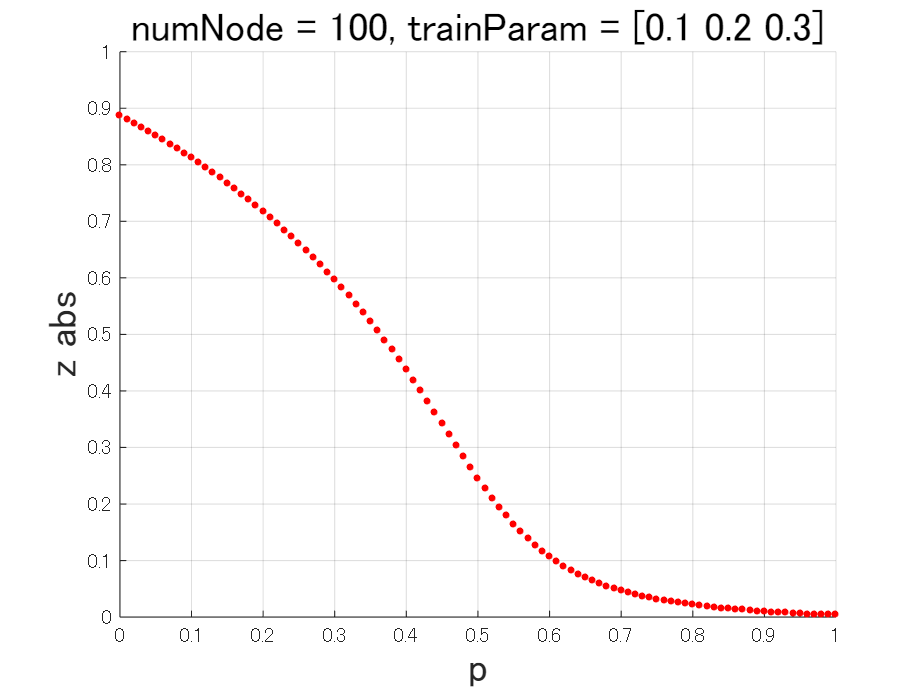

fontsize = 18; % フォントサイズ

% train_param を文字列に変換して結合
train_param_str = sprintf('%.2f_', train_param); % 各値を文字列に変換し、'_'で結合
train_param_str = train_param_str(1:end-1); % 最後の余分な'_'を削除

% ファイル名を生成
filename = sprintf('plotFile/p=[%s].pdf', train_param_str);

% 分岐図をプロット
figure;
hold on;
scatter(par, z_abs_data, 10, 'red', 'filled');
xlabel('p', 'FontSize', fontsize); % フォントサイズを設定
ylabel('z abs', 'FontSize', fontsize); % 縦軸ラベル
title('numNode = 100, trainParam = [0.1 0.2 0.3]', 'FontSize', fontsize); % タイトル
ylim([0 1.2]); % y軸の範囲を設定
grid on;
hold off;


% プロットをPDFに保存
exportgraphics(gcf, filename, 'Append', true); % 'Append'でPDFに追加

次を使用中のエラー: exportgraphics
'destination' の値は無効です。 出力ファイル 'plotFile/p=[0.10_0.20_0.30].pdf' を作成できません。Permission denied

close(gcf); % 図を閉じる
toc; % 実行時間を測定